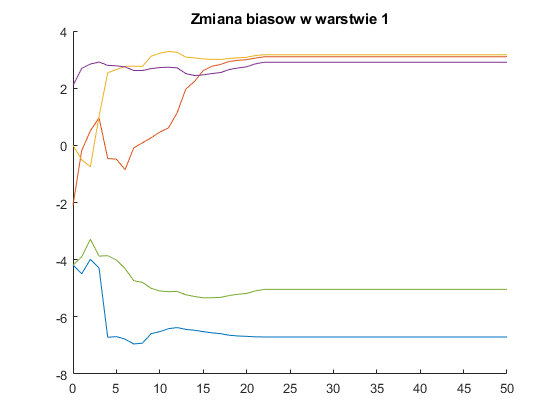

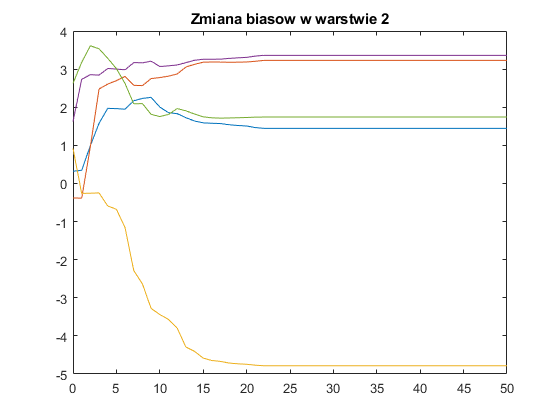

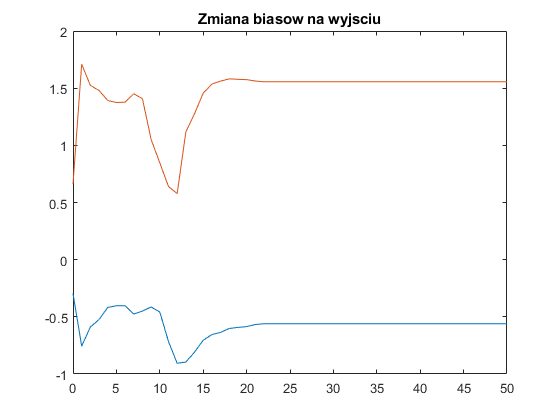

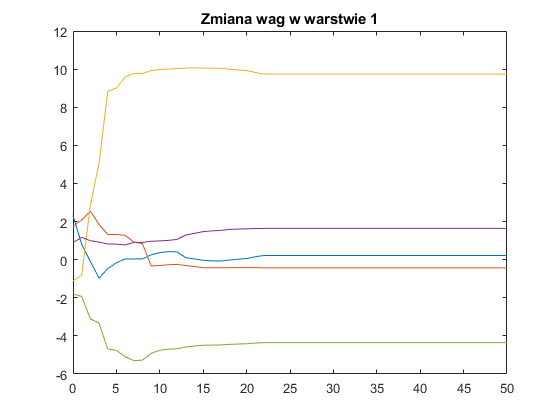

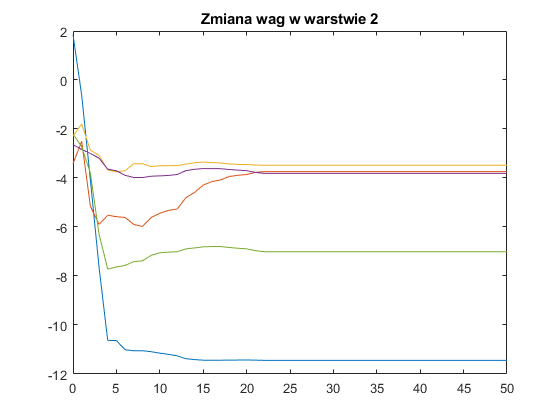

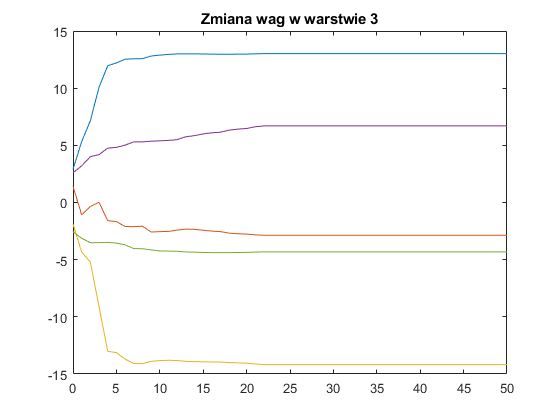

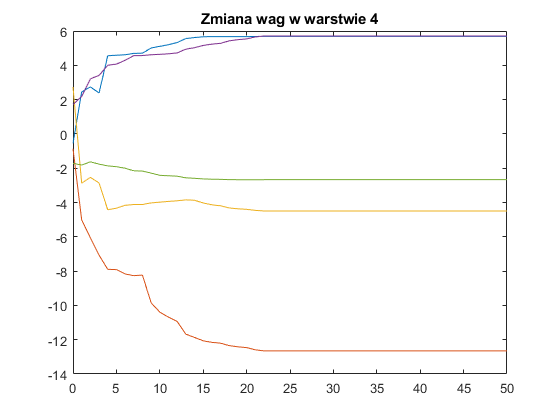

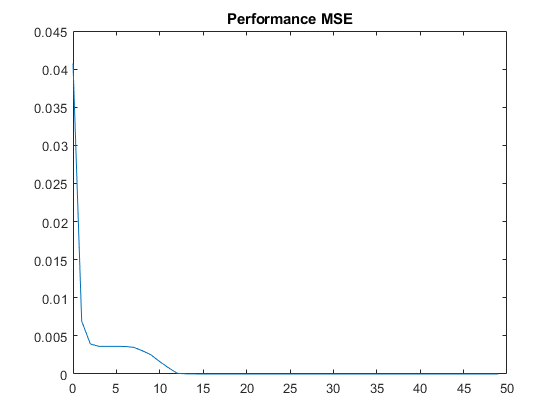

accuracy = 100

clear; clc;

% SSNvisualisation(5, 50);

SSNvisualisation([5 5], 50);


% SSNvisualisation([1 2 3 4], 50);


function SSNvisualisation(layers, epochs)
    load iris_dataset; % defaultowy dataset

    % podzial danych na klasy

    klasa1_train = irisInputs(:,(1:45));
    klasa1_test = irisInputs(:,(46:50));
    klasa2_train = irisInputs(:,(51:95));
    klasa2_test = irisInputs(:,(96:100));
    klasa3_train = irisInputs(:,(101:145));
    klasa3_test = irisInputs(:,(146:150));

    % tworzenie danych uczacych

    train_in = [klasa1_train, klasa2_train, klasa3_train];
    train_out = [repmat([0,1], length(klasa1_train), 1);repmat([1,0], length(klasa1_train), 1);repmat([1,1], length(klasa1_train), 1)]';

    net = feedforwardnet(layers); % dwie warstwy
    net.layers{1}.transferFcn = 'logsig';
    net.layers{2}.transferFcn = 'tansig';
    net.divideFcn = 'dividetrain';
    net = configure(net, train_in, train_out); % konfiguracja na trainin i trainout

%     epochs = 50; % tutaj mozemy machac epokami jak chcemy

    net.trainParam.epochs = 5; % to epoki z neta, ustawilem tyle, zeby cos tam sie uczylo

    % inicjalizacje zmiennych
    weights = net.IW{1}; 
    % biases = net.b{1};


    % new_weights = net.IW; 
    new_biases = net.b;

    % declare variable to store mse err
    mseOut = [];
    
    % trenowanko i zbieranie danych
    for i=1:epochs
        net = train(net, train_in, train_out);
        weights(:, :, i + 1) = net.IW{1};
    %     biases(:, :, i + 1) = net.b{1};

    %     new_weights(:, i+1) = net.IW; 
        new_biases(:, i+1) = net.b;
        
        % mse err
        trainOut = net(train_in);
        [~,mseOut(i),~,~] = measerr(trainOut,train_out);
        
    end

    % obrobka i wyswietlanie danych
        x = linspace(0, epochs, epochs+1);
    %     % biasy
    %     for i=1:length(biases(:,1,1))
    %         b_tmp = zeros(1, epochs+1);
    %         for j=1:epochs+1
    %             b_tmp(j) = biases(i, 1, j);
    %         end
    %         plot(x, repmat(b_tmp,1));
    %     end
        for i=1:length(new_biases(:,1))
            for j=1:length(cell2mat(new_biases(i,1)))
                b_tmp = zeros(1, epochs+1);
                for k=1:length(new_biases(1,:))
                    biases_array_tmp = cell2mat(new_biases(i, k));
                    b_tmp(k) = biases_array_tmp(j);
                end
                hold on
                figure(i)
                if i == length(new_biases(:,1))
                    title("Zmiana biasow na wyjsciu")
                else
                    title("Zmiana biasow w warstwie " + int2str(i))
                end
                plot(x, repmat(b_tmp,1));
                hold off
            end
        end
        % wagi
        for i=1:length(weights(1,:,1))
            for j=1:length(weights(:,1,1))
                w_tmp = zeros(1, epochs+1);
                for k=1:epochs+1
                    w_tmp(k) = weights(j, i, k);
                end
                hold on
                figure(i+length(new_biases(:,1)))
                title("Zmiana wag w warstwie " + int2str(i))
                plot(x, repmat(w_tmp,1));
                hold off
            end
        end

    hold on
    figure(2*length(new_biases(:,1))+3)
    plot(x(1:epochs),mseOut(:))
    title("Performance MSE")
    hold off


    % sprawdzenie, czy siec sie dobrze wytrenowala

    ytest1 = round(net(klasa1_test)');
    ytest2 = round(net(klasa2_test)');
    ytest3 = round(net(klasa3_test)');

    ok = 0;

    for i=1:5
       if ytest1(i,1) == 0 &&  ytest1(i,2) == 1
            ok = ok + 1;
       end
       if ytest2(i,1) == 1 &&  ytest2(i,2) == 0
            ok = ok + 1;
       end
       if ytest3(i,1) == 1 &&  ytest3(i,2) == 1
            ok = ok + 1;
       end

    end

    accuracy = ok/15 * 100
end